#  ТАУ. Лаба №11

## Задание №1

% w1 = tf([4],[1 0.2 9])
% w2 = tf([5],[1 2])
% w3 = tf([20],[1 2])
% w4 = tf([2],[1 0.2 1])
% w5 = tf([10],[1 5])
% w6 = tf([10],[1 5])
% 
% A = [w1 w2 w5;
%     w3 w4 w6]
% B = [w1 w2;
%     w3 0;
%     w4 w5;
%     w2 w1;
%     0 w2]

% Построение графиков АЧХ компонент матрицы А

% bode(w1)
% hold on
% grid on
% bode(w2)
% bode(w3)
% bode(w4)
% bode(w5)
% bode(w6)
% hold off
% legend('Компонента 1','Компонента 2','Компонента 3', 'Компонента 4','Компонента 5','Компонента 6')
% title('АЧХ компонент матрицы ')
% hold off

% Построение графика зависимости сингулярных чисел от частоты матрицы А

% [sw, wout] = sigma(A);
% plot(wout, sw)
% title('Зависимость сингулярных чисел от частоты матрицы А')
% Вычисление H_2 и H_∞ норм матрицы А
% H2_A = norm(A,2)
% Hinf_A = norm(A,inf)
% 

% Построение графиков АЧХ компонент матрицы В

% bode(w1)
% hold on
% grid on
% bode(w2)
% bode(w3)
% bode(w4)
% hold off
% legend('Компонента 1','Компонента 2','Компонента 3', 'Компонента 4')
% title('АЧХ компонент матрицы ')
% hold off

% Построение графика зависимости сингулярных чисел от частоты матрицы В

% [sw, wout] = sigma(B);
% plot(wout, sw)
% title('Зависимость сингулярных чисел от частоты матрицы B')

% Вычисление H_2 и H_∞ норм матрицы В

% H2_B = norm(B,2)
% Hinf_B = norm(B,"inf")

## Задание №2

% A = [0 1;
%     0 0]
% B_1 = [1;
%     1]
% B_2 = [0;1]

Подбираем C и D.

% C = [0 0;
%     1 1]
% D = [1; 0]
% C'*D
% det(D'*D)

,

Далее синтезируем регулятор

% C = C_2
% D = D_2
% Q = are(A, B_2*inv(D'*D)*B_2', C'*C)
% K = -inv(D'*D)*B_2'*Q

Найдем передаточную функцию

% W = tf(ss(A+B_2*K,B_1,C+D*K,[0]))

Построим для нее график покомпонентых АЧХ и график сингулярных чисел. Вычислим $H_2$ и $H_{\infty }$-нормы.

Строим W

% syms s;
% w1 = tf([-15.18 -1],[1 0.1418 0.1]) 
% w2 = tf([2 1.132],[1 0.1418 0.1]) 
% bode(w1)
% hold on
% bode(w2)
% grid on
% legend('Компонента 1','Компонента 2')
% title('АЧХ компонент матрицы ')
% hold off

Строим график сингулярных чисел 

% [sw, wout] = sigma(W)
% plot(wout, sw)
% title('Сингулярные числа')

Далее считаем нормы

% H2_w = norm(W,2)
% Hinf_w = norm(W,'inf')

Строим графики при импульсном и степ возмущениях

% times = 0:0.001:60;
% [x_1, impulse_times] = impulse(ss(A+B_2*K, B_1, C+D*K, [0]), times(length(times)));
% plot(impulse_times, x_1);
% grid on
% 
% [x_2, step_times] = step(ss(A+B_2*K, B_1, C+D*K, [0]), times(length(times)));
% plot(step_times, x_2);
% grid on

## Задание №3

% A = [0 1;0 0];
% B_1 = [1;1]; %внешние возмущения
% B_2 = [0;1];
% C = C_2
% D = D_2
% C_1 = [1 0];
% D_1 = [1]; %помеха измерения

Найдем Р и Q как решения алгебраических уравнений Риккати,  матрицу регулятора K и матрицу наблюдателя L.

% Q = are(A, B_2*inv(D'*D)*B_2', C'*C);
% K = -inv(D'*D)*B_2'*Q
% 
% P = are(A', C_1'*inv(D_1'*D_1)*C_1, B_1*B_1');
% L = -P*C_1'*inv(D_1'*D_1)

Найдем передаточную матрицу

% A_obsv = [A B_2*K; -L*C_1 A+B_2*K+L*C_1];
% B_obsv = [B_1; -L*D_1];
% C_obsv = [C D*K];
% W = tf(ss(A_obsv, B_obsv, C_obsv, [0]))

Нормы

% W_h2 = norm(W, 2)
% W_hinf = norm(W, Inf)

Строим графики

% bode(W)
% [sw, wout] = sigma(W)
% plot(wout, sw)
% title('Сингулярные числа')

## Задание №4

% A = [0 1;
%     0 0]
% B_1 = [1;
%     1]
% B_2 = [0;1]

Подбираем C и D.

% C_2 = [0 0;
%     1 1]
% D_2 = [1; 0]
% C_2'*D_2
% det(D_2'*D_2)

выбраные значения

% gamma1 = 50
% gamma2 = 25
% gamma3 = 5
% gamma4 = 1.5

Синтезируем регуляторы и наблюдатели для каждого случая

% Q_1 = are(A, B_2*inv(D_2'*D_2)*B_2'-gamma1^(-2)*B_1*B_1', C_2'*C_2);
% K_1 = -inv(D_2'*D_2)*B_2'*Q_1
% 
% Q_2 = are(A, B_2*inv(D_2'*D_2)*B_2'-gamma2^(-2)*B_1*B_1', C_2'*C_2);
% K_2 = -inv(D_2'*D_2)*B_2'*Q_2
% 
% Q_3 = are(A, B_2*inv(D_2'*D_2)*B_2'-gamma3^(-2)*B_1*B_1', C_2'*C_2);
% K_3 = -inv(D_2'*D_2)*B_2'*Q_3
% 
% Q_4 = are(A, B_2*inv(D_2'*D_2)*B_2'-gamma4^(-2)*B_1*B_1', C_2'*C_2);
% K_4 = -inv(D_2'*D_2)*B_2'*Q_4

вычисляем передаточные  функции и нормы

% W_1 = tf(ss(A+B_2*K_1,B_1,C_2+D_2*K_1,[0]))
% W_h2 = norm(W_1, 2)
% W_hinf = norm(W_1, Inf)
% 
% W_2 = tf(ss(A+B_2*K_2,B_1,C_2+D_2*K_2,[0]))
% W_h2 = norm(W_2, 2)
% W_hinf = norm(W_2, Inf)
% 
% W_3 = tf(ss(A+B_2*K_3,B_1,C_2+D_2*K_3,[0]))
% W_h2 = norm(W_3, 2)
% W_hinf = norm(W_3, Inf)
% 
% W_4 = tf(ss(A+B_2*K_4,B_1,C_2+D_2*K_4,[0]))
% W_h2 = norm(W_4, 2)
% W_hinf = norm(W_4, Inf)

Строим графики

% bode(W_1)
% [sw, wout] = sigma(W_1)
% plot(wout, sw)
% 
% bode(W_2)
% [sw, wout] = sigma(W_2)
% plot(wout, sw)
% 
% bode(W_3)
% [sw, wout] = sigma(W_3)
% plot(wout, sw)
% 
% bode(W_4)
% [sw, wout] = sigma(W_4)
% plot(wout, sw)

Для самого маленького из выбранных значений $\gamma =0\ldotp 1$ проведем моделирование замкнутой системы при разных внешних воздействиях

% times = 0:0.001:60;
% K = K_4
% [x_1, impulse_times] = impulse(W_4, times(length(times)));
% plot(impulse_times, x_1)
% grid on
% 
% [x_2, step_times] = step(W_4, times(length(times)));
% plot(step_times, x_2)
% grid on
% 
% x = lsim(W_4, sin(0.1*times), times, [0;0]);
% plot(times, x)

## Задание №5

A = [0 1;0 0];
B1 = [1;1]; %внешнее возмущение
B2 = [0;1];
C1 = [1 0];
C2 = [0 0;
    1 1]

C2 =      0     0
     1     1


D2 = [1; 0]

D2 =      1
     0


D1 = [1]; %помеха измерения

Выберем 4 различных значения параметра $\gamma >0$. 

gamma1 = 50

gamma1 = 50

gamma2 = 25

gamma2 = 25

gamma3 = 5

gamma3 = 5

gamma4 = 2.8

gamma4 = 2.8000

Для каждого из значений $\gamma$ синтезируем соответствующий $H_{\infty }$-регулятор по выходу, включающий в себя наблюдатель. Для этого найдем матрицы P и Q как решения алгебраических уравнений Риккати, а затем матрицы коэффициентов регулятора K и наблюдателя L.

Q1 = are(A, B2*inv(D2'*D2)*B2'-gamma1^(-2)*B1*B1', C2'*C2);
K1 = -inv(D2'*D2)*B2'*Q1

K1 =    -1.0006   -1.7333


P1 = are(A', C1'*inv(D1*D1')*C1-gamma1^(-2)*C2'*C2, B1*B1');
L1 = -P1*inv(eye(2)-gamma1^(-2)*Q1*P1)*(C1+gamma1^(-2)*D1*B1'*Q1)'*inv(D1*D1')

L1 =    -1.7385
   -1.0040



Q2 = are(A, B2*inv(D2'*D2)*B2'-gamma2^(-2)*B1*B1', C2'*C2);
K2 = -inv(D2'*D2)*B2'*Q2

K2 =    -1.0024   -1.7369


P2 = are(A', C1'*inv(D1*D1')*C1-gamma2^(-2)*C2'*C2, B1*B1');
L2 = -P2*inv(eye(2)-gamma2^(-2)*Q2*P2)*(C1+gamma2^(-2)*D1*B1'*Q2)'*inv(D1*D1')

L2 =    -1.7582
   -1.0162



Q3 = are(A, B2*inv(D2'*D2)*B2'-gamma3^(-2)*B1*B1', C2'*C2);
K3 = -inv(D2'*D2)*B2'*Q3

K3 =    -1.0653   -1.8638


P3 = are(A', C1'*inv(D1*D1')*C1-gamma3^(-2)*C2'*C2, B1*B1');
L3 = -P3*inv(eye(2)-gamma3^(-2)*Q3*P3)*(C1+gamma3^(-2)*D1*B1'*Q3)'*inv(D1*D1')

L3 =    -2.6468
   -1.5688



Q4 = are(A, B2*inv(D2'*D2)*B2'-gamma4^(-2)*B1*B1', C2'*C2);
K4 = -inv(D2'*D2)*B2'*Q4

K4 =    -1.2585   -2.2568


P4 = are(A', C1'*inv(D1*D1')*C1-gamma4^(-2)*C2'*C2, B1*B1');
L4 = -P2*inv(eye(2)-gamma4^(-2)*Q4*P4)*(C1+gamma4^(-2)*D1*B1'*Q4)'*inv(D1*D1')

L4 =   -28.3484
  -18.3365


Проверим условие согласованности для найденных наборов (P, Q).

max(eigs(P1*Q1))<gamma1^2

ans = logical
   1


max(eigs(P2*Q2))<gamma2^2

ans = logical
   1


max(eigs(P3*Q3))<gamma3^2

ans = logical
   1


max(eigs(P4*Q4))<gamma4^2

ans = logical
   1


В каждом случае найдем передаточную функцию (матрицу) замкнутой системы от внешних сигналов (возмущений и помех) к регулируемому выходу. За вектор состояния замкнутой системы с наблюдателем выбран объединенный вектор состояния и вектор оценки состояния системы. 

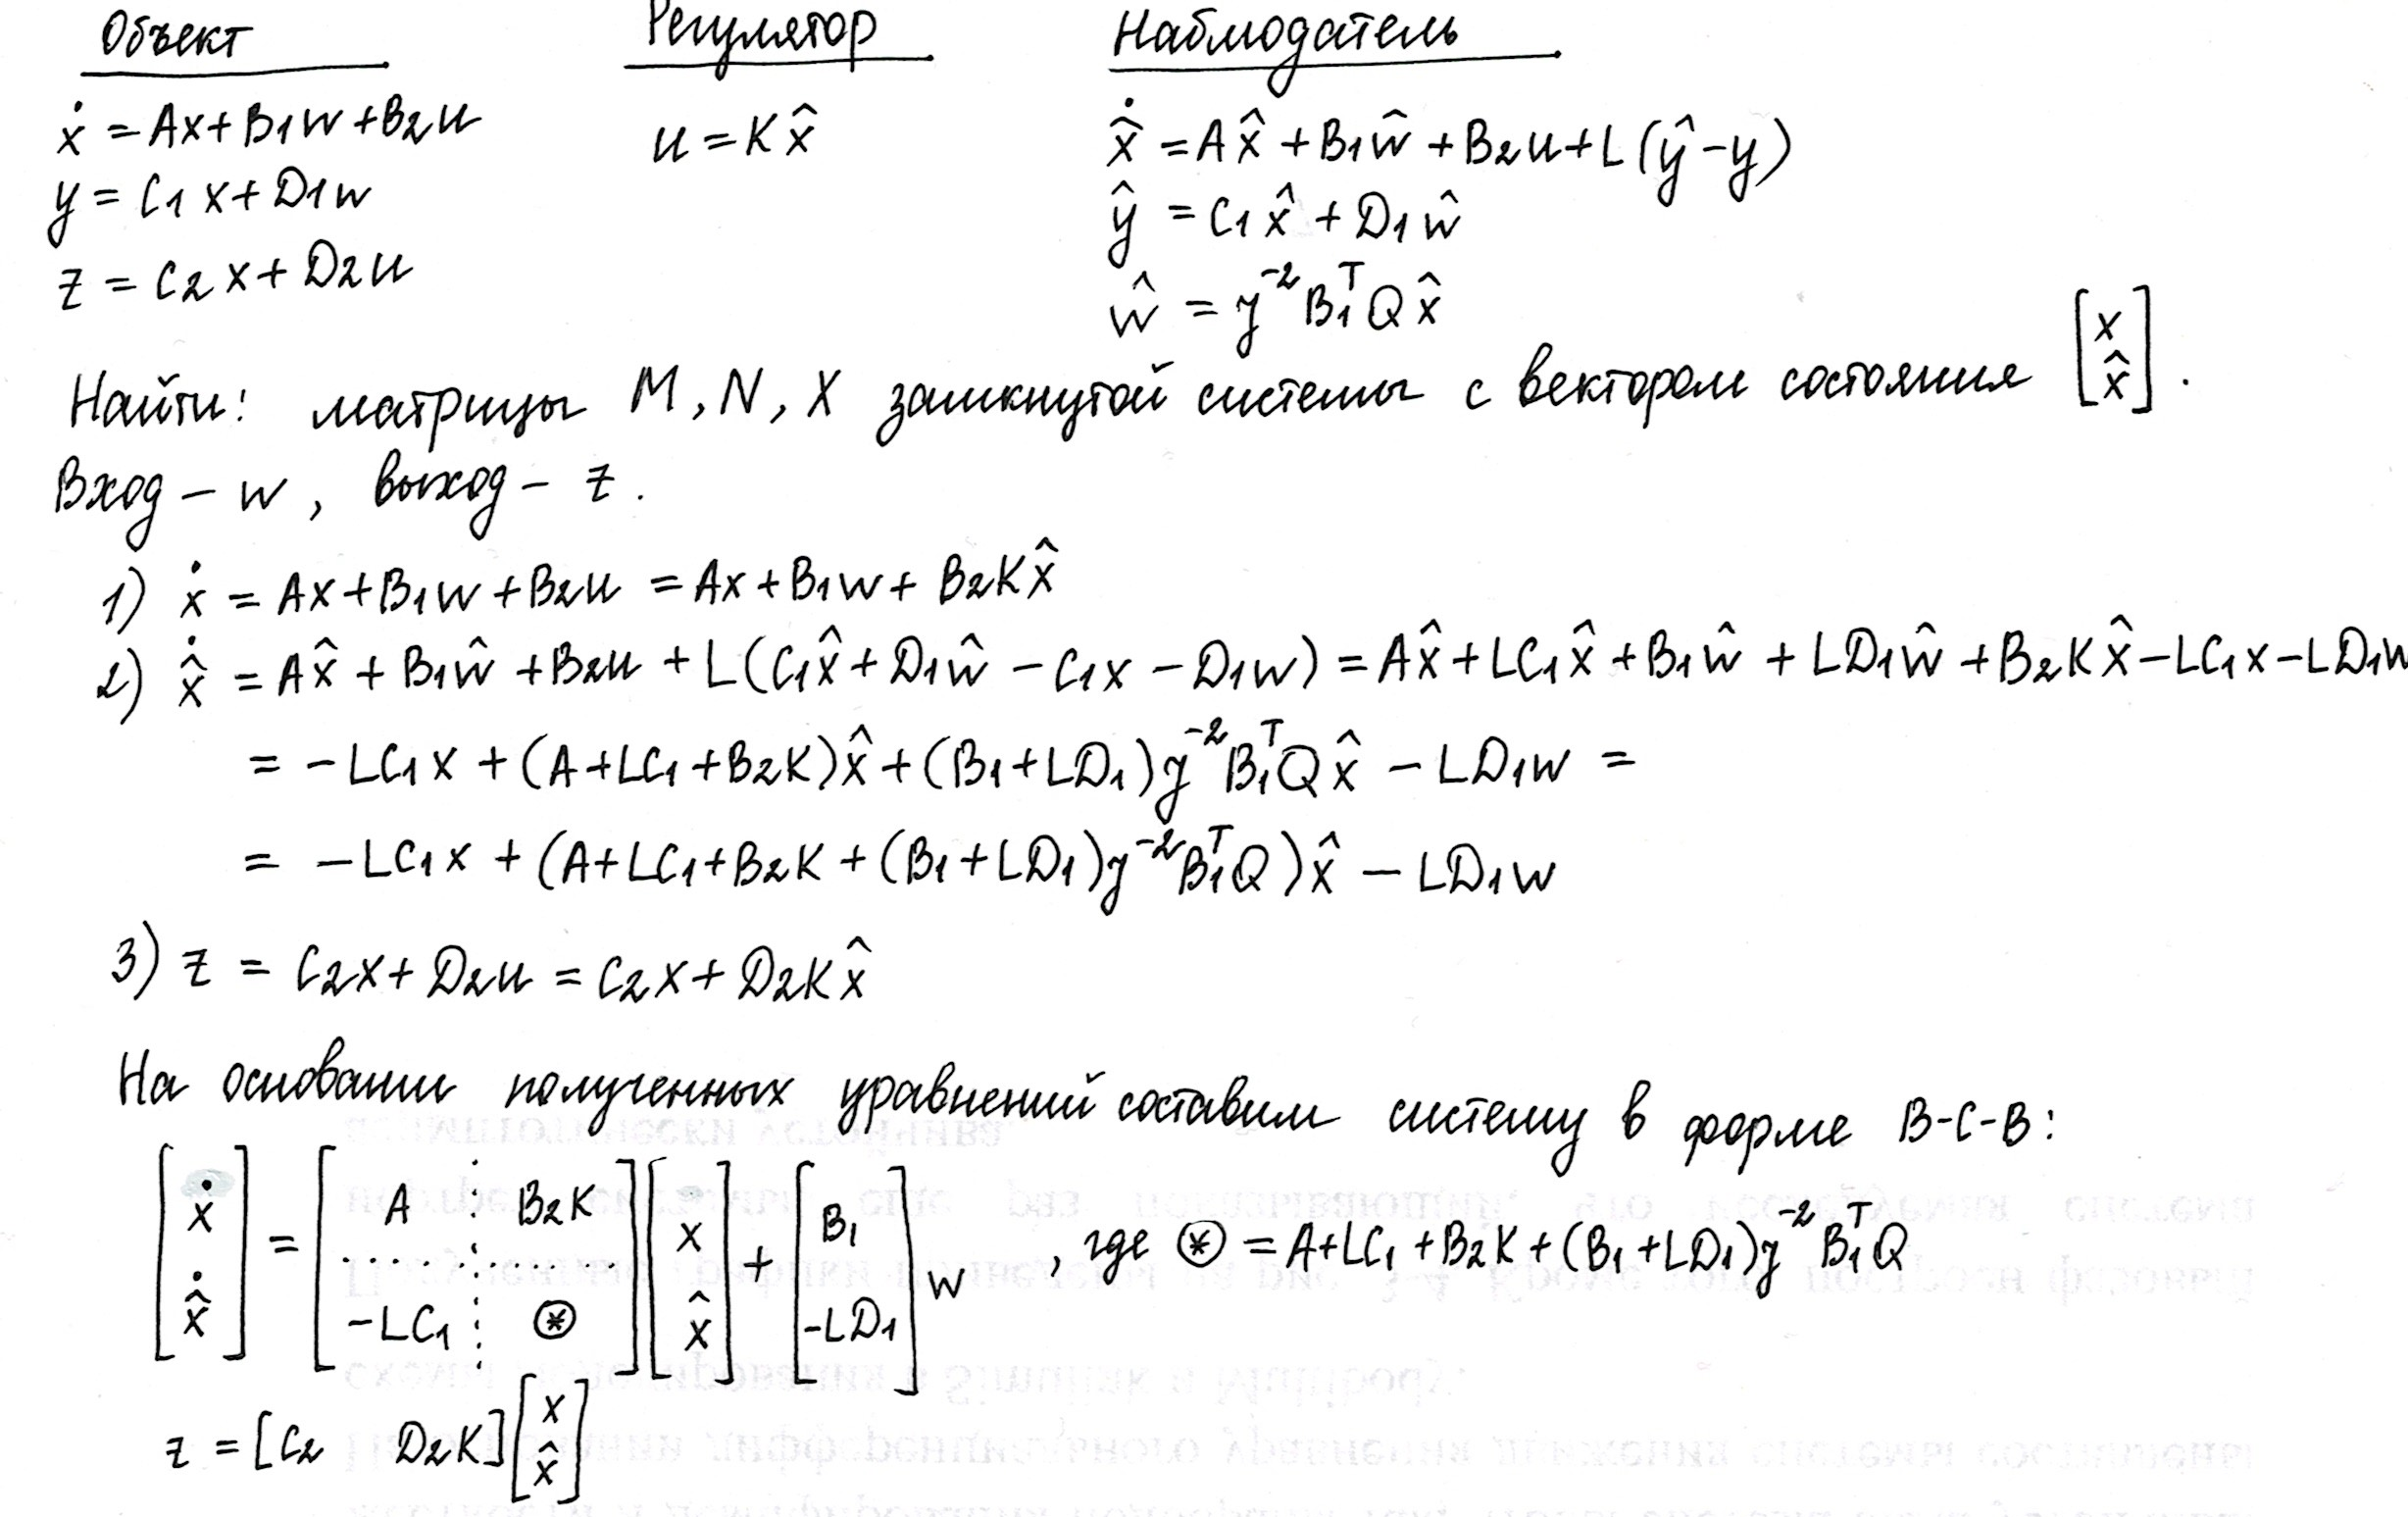

Найдем $H_2 \;и\;H_{\infty } \;$нормы матриц.

A_obsv = [A B2*K1; -L1*C1 A+L1*C1+B2*K1+(B1+L1*D1)*gamma1^(-2)*B1'*Q1];
B_obsv = [B1; -L1*D1];
C_obsv = [C2 D2*K1];
H1 = tf(ss(A_obsv, B_obsv, C_obsv, [0]))

H1 =
 
  From input to output...
         -3.48 s^3 - 4.485 s^2 - 4.485 s - 1.005
   1:  --------------------------------------------
       s^4 + 3.472 s^3 + 5.017 s^2 + 3.48 s + 1.005
 
           2 s^3 + 4.465 s^2 + 5.542 s + 3.008
   2:  --------------------------------------------
       s^4 + 3.472 s^3 + 5.017 s^2 + 3.48 s + 1.005
 
Continuous-time transfer function.




W_h2_1 = norm(H1, 2)

W_h2_1 = 2.2548

W_hinf = norm(H1, Inf)

W_hinf = 3.1563


A_obsv = [A B2*K2; -L2*C1 A+L2*C1+B2*K2+(B1+L2*D1)*gamma2^(-2)*B1'*Q2];
B_obsv = [B1; -L2*D1];
C_obsv = [C2 D2*K2];
H2 = tf(ss(A_obsv, B_obsv, C_obsv, [0]))

H2 =
 
  From input to output...
         -3.528 s^3 - 4.547 s^2 - 4.547 s - 1.019
   1:  --------------------------------------------
       s^4 + 3.497 s^3 + 5.07 s^2 + 3.528 s + 1.019
 
           2 s^3 + 4.467 s^2 + 5.562 s + 3.032
   2:  --------------------------------------------
       s^4 + 3.497 s^3 + 5.07 s^2 + 3.528 s + 1.019
 
Continuous-time transfer function.




W_h2_2 = norm(H2, 2)

W_h2_2 = 2.2559

W_hinf = norm(H2, Inf)

W_hinf = 3.1385


A_obsv = [A B2*K3; -L3*C1 A+L3*C1+B2*K3+(B1+L3*D1)*gamma3^(-2)*B1'*Q3];
B_obsv = [B1; -L3*D1];
C_obsv = [C2 D2*K3];
H3 = tf(ss(A_obsv, B_obsv, C_obsv, [0]))

H3 =
 
  From input to output...
         -5.743 s^3 - 7.428 s^2 - 7.428 s - 1.684
   1:  ---------------------------------------------
       s^4 + 4.698 s^3 + 7.502 s^2 + 5.743 s + 1.684
 
            2 s^3 + 4.653 s^2 + 6.532 s + 4.134
   2:  ---------------------------------------------
       s^4 + 4.698 s^3 + 7.502 s^2 + 5.743 s + 1.684
 
Continuous-time transfer function.




W_h2_3 = norm(H3, 2)

W_h2_3 = 2.4689

W_hinf = norm(H3, Inf)

W_hinf = 2.6505


A_obsv = [A B2*K4; -L4*C1 A+L4*C1+B2*K4+(B1+L4*D1)*gamma4^(-2)*B1'*Q4];
B_obsv = [B1; -L4*D1];
C_obsv = [C2 D2*K4];
H4 = tf(ss(A_obsv, B_obsv, C_obsv, [0]))

H4 =
 
  From input to output...
         -77.06 s^3 - 100.7 s^2 - 100.7 s - 23.59
   1:  ---------------------------------------------
       s^4 + 45.84 s^3 + 85.22 s^2 + 77.06 s + 23.59
 
            2 s^3 + 15.62 s^2 + 38.58 s + 38.04
   2:  ---------------------------------------------
       s^4 + 45.84 s^3 + 85.22 s^2 + 77.06 s + 23.59
 
Continuous-time transfer function.




W_h2_4 = norm(H4, 2)

W_h2_4 = 8.1694

W_hinf = norm(H4, Inf)

W_hinf = 1.8972

Построим графики графики покомпонентных АЧХ и графики сингулярных чисел для каждого значения $\gamma$.

number=1

number = 1

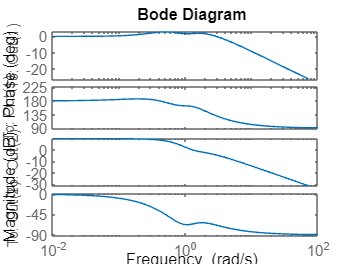

bode(H1)

[sw, wout] = sigma(H1)

sw =     3.1562    3.1562    3.1562    3.1561    3.1561    3.1560    3.1559    3.1557    3.1555    3.1552    3.1548    3.1542    3.1534    3.1523    3.1508    3.1487    3.1476    3.1458    3.1416    3.1356    3.1270    3.1143    3.0955    3.0673    3.0247    2.9607    2.8658    2.7291    2.5424    2.3079    2.0485    1.8109    1.7499    1.6436    1.5566    1.5132    1.4682    1.3988    1.3034    1.1904    1.0696    0.9491    0.8344    0.7286    0.6329    0.5477    0.4727    0.4072    0.3957    0.3502


wout =     0.0100
    0.0107
    0.0125
    0.0146
    0.0171
    0.0199
    0.0232
    0.0271
    0.0317
    0.0370


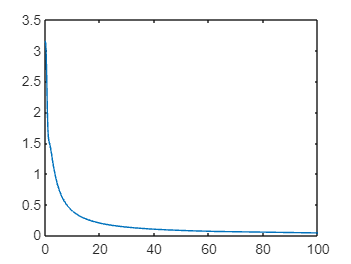

    plot(wout, sw)


number=2

number = 2

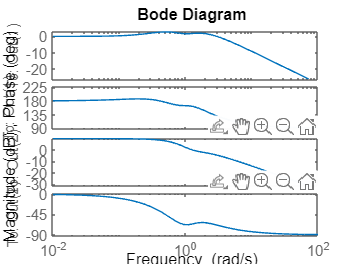

bode(H2)

[sw, wout] = sigma(H2)

sw =     3.1385    3.1385    3.1384    3.1384    3.1383    3.1382    3.1381    3.1379    3.1377    3.1374    3.1369    3.1364    3.1355    3.1344    3.1329    3.1307    3.1295    3.1277    3.1234    3.1173    3.1084    3.0955    3.0764    3.0478    3.0049    2.9407    2.8457    2.7093    2.5235    2.2907    2.0339    1.7996    1.7417    1.6360    1.5528    1.5126    1.4702    1.4028    1.3087    1.1963    1.0757    0.9552    0.8401    0.7338    0.6376    0.5519    0.4764    0.4104    0.3996    0.3530


wout =     0.0100
    0.0107
    0.0125
    0.0146
    0.0171
    0.0199
    0.0233
    0.0272
    0.0317
    0.0370


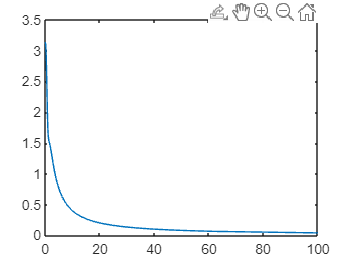

    plot(wout, sw)

number=3

number = 3

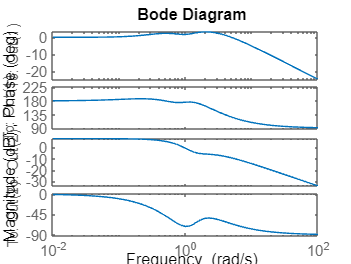

bode(H3)

[sw, wout] = sigma(H2)

sw =     3.1385    3.1385    3.1384    3.1384    3.1383    3.1382    3.1381    3.1379    3.1377    3.1374    3.1369    3.1364    3.1355    3.1344    3.1329    3.1307    3.1295    3.1277    3.1234    3.1173    3.1084    3.0955    3.0764    3.0478    3.0049    2.9407    2.8457    2.7093    2.5235    2.2907    2.0339    1.7996    1.7417    1.6360    1.5528    1.5126    1.4702    1.4028    1.3087    1.1963    1.0757    0.9552    0.8401    0.7338    0.6376    0.5519    0.4764    0.4104    0.3996    0.3530


wout =     0.0100
    0.0107
    0.0125
    0.0146
    0.0171
    0.0199
    0.0233
    0.0272
    0.0317
    0.0370


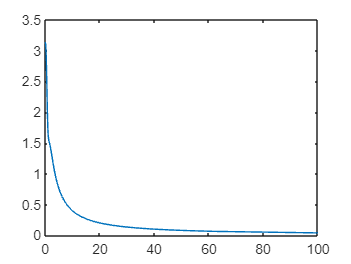

    plot(wout, sw)

number=4

number = 4

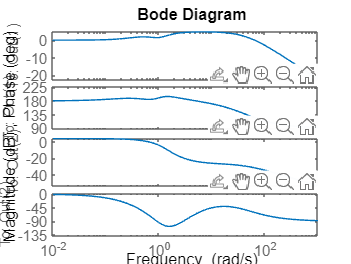

bode(H4)

[sw, wout] = sigma(H4)

sw =     1.8972    1.8972    1.8971    1.8971    1.8971    1.8970    1.8969    1.8968    1.8966    1.8964    1.8961    1.8956    1.8950    1.8942    1.8931    1.8916    1.8914    1.8895    1.8867    1.8827    1.8772    1.8695    1.8587    1.8434    1.8218    1.7912    1.7481    1.6885    1.6095    1.5132    1.4141    1.3418    1.3387    1.3243    1.3617    1.4284    1.4988    1.5600    1.6083    1.6448    1.6714    1.6902    1.7029    1.7106    1.7141    1.7139    1.7099    1.7019    1.7018    1.6893


wout = 1.0e+03 *

    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000


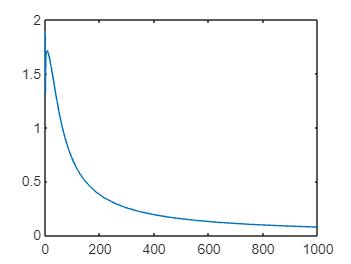

    plot(wout, sw)

Для самого маленького из выбранных значений $\gamma =1,5$ проведем моделирование замкнутой системы при разных внешних воздействиях 

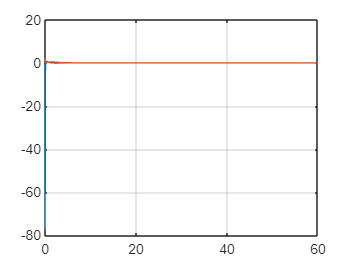

times = 0:0.001:60;
[x_1, impulse_times] = impulse(H4, times(length(times)));
plot(impulse_times, x_1)
grid on

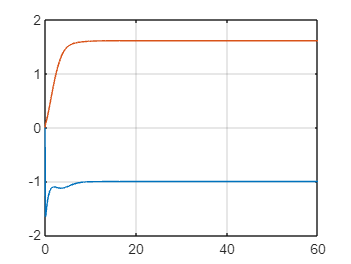


[x_2, step_times] = step(H4, times(length(times)));
plot(step_times, x_2)
grid on

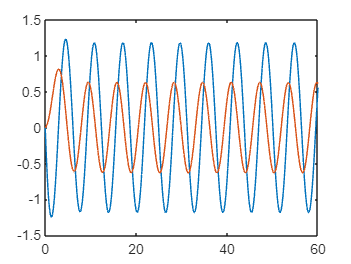


x = lsim(H4, sin(1*times), times, [0;0]);
plot(times, x)